# Laboratorio final robótica 2021-1

### UNAL 

Kevin Andres Ramirez Gutierrez - kearamirezgu

David Andrés Rivas Gonzalez - darivasg

Jefferson David Rojas Avellaneda - jedrojasav

Manuel Alejandro Rojas Cubillos - maarojascu

**REPOSITORIO: **

[jedrojasav/Laboratorio-Robotica: Laboratorio final robótica 2021-1 (github.com)](https://github.com/jedrojasav/Laboratorio-Robotica)

**WIKIDOT:**

[Home - Análisis y simulación de robot industrial FANUC M-16iB (wikidot.com)](http://labunalfanucm16ib.wikidot.com/)

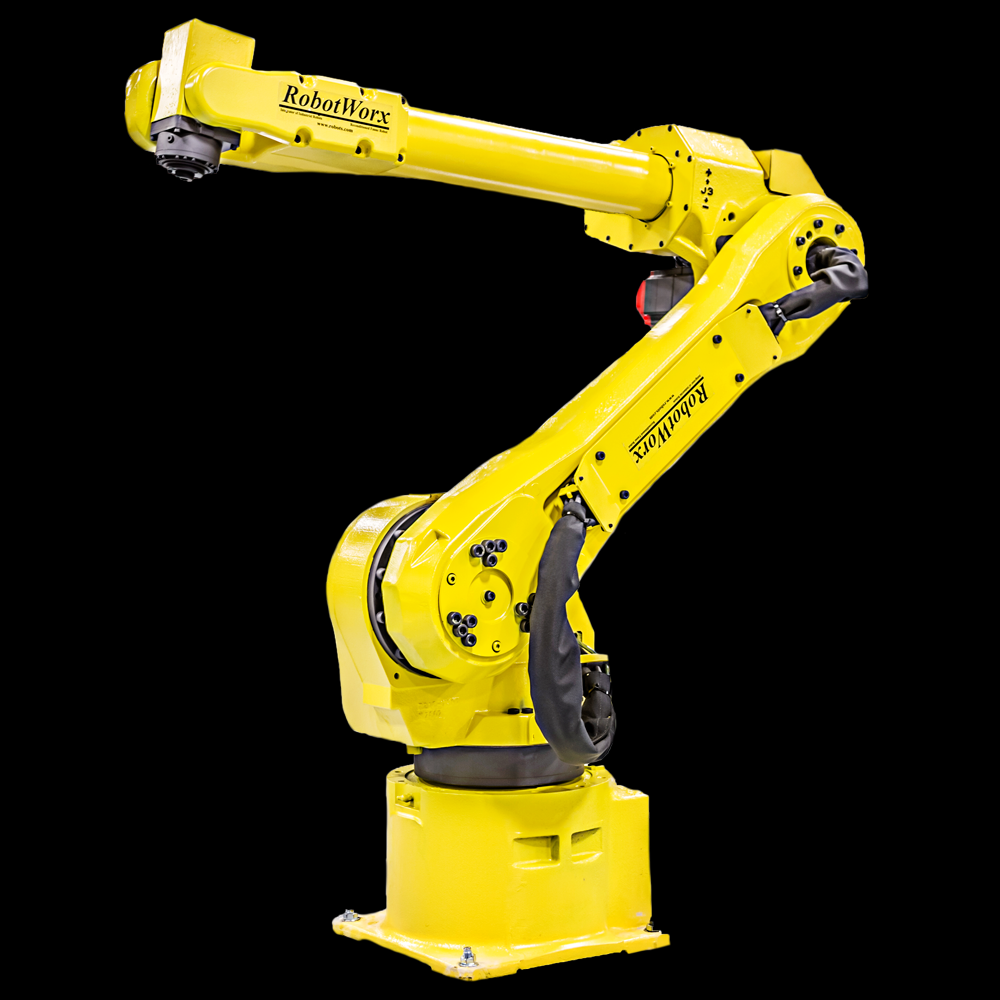

Figura 1. Robot Fanuc M16

El FANUC M-16iB es un robot eléctrico servoaccionado de construcción modular de seis ejes diseñado para una variedad de aplicaciones industriales. Basado en su construcción simple y confiable, el FANUC M16iB RJ3iB proporciona un control de movimiento sofisticado y un rendimiento constante con alta productividad. Tiene una de las áreas de trabajo y capacidades de carga más grandes de su clase.[Robotworx, 2021]

En el presente documento se hace un análisis y modelado del robot usando cinemática directa, inversa y su modelo diferencial de primer orden.

### Modelos

- Se hace el análisis geométrico del robot y se llega a la siguiente tabla de parámetros DHmod:

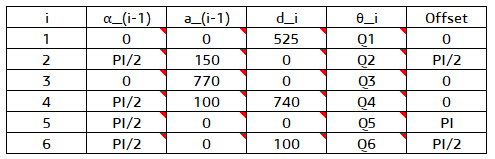

Una vez obtenida la tabla se procede a crear el modelo del robot usando el toolbox de peter corke por medio de las funciones Link y serialLink

clear; clc;
l1 = 525; l2=150; l3=770; l4=100; l5=740; l6=100; 
q1 = 0; q2=0; q3=0; q4=0; q5=0; q6=0;  % Valores Home 
q =  [q1 q2 q3 q4 q5 q6];

ws = [-1500 1500 -1500 1000 -50 2400];
plot_options = {'workspace',ws,'scale',.5,'view',[135 45],'tilesize',2,'ortho','lightpos',[100 100 100]};

L(1) = Link('revolute', 'alpha', 0,     'a',  0,    'd',    l1, 'offset',       0,  'qlim', [-pi pi],'modified');
L(2) = Link('revolute', 'alpha', pi/2,  'a', l2,    'd',    0,  'offset',    pi/2,  'qlim', [-pi/2 8*pi/9], 'modified') ;
L(3) = Link('revolute', 'alpha', 0,     'a', l3,    'd',    0,  'offset',       0,  'qlim', [-17*pi/18 29*pi/18], 'modified');
L(4) = Link('revolute', 'alpha', pi/2,  'a', l4,    'd',    l5,  'offset',       0,  'qlim', [-10*pi/9 10*pi/9], 'modified');
L(5) = Link('revolute', 'alpha', pi/2,  'a',  0,    'd',    0,  'offset',     pi,  'qlim', [-7*pi/4 7*pi/4], 'modified');
L(6) = Link('revolute', 'alpha', pi/2,  'a',  0,    'd',    l6,  'offset',   pi/2,  'qlim', [-5*pi/2 5*pi/2], 'modified');

Robot = SerialLink (L,'name','Fanuc','plotopt',plot_options)

 
Robot = 
 
Fanuc (6 axis, RRRRRR, modDH, fastRNE)                           
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        525|          0|          0|          0|
|  2|         q2|          0|        150|      1.571|      1.571|
|  3|         q3|          0|        770|          0|          0|
|  4|         q4|        740|        100|      1.571|          0|
|  5|         q5|          0|          0|      1.571|      3.142|
|  6|         q6|        100|          0|      1.571|      1.571|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0            

Se observa que la tabla de parámetros obtenida es igual a la que se planteó en un inicio por lo que se procede a ver el robot en forma gráfica:

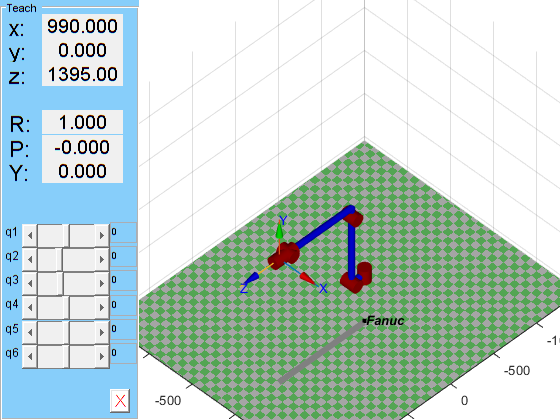

Robot.teach(q)

- Modelacion usando RST

%Se define la tabla con los parametros DH
dhparams = [0   	0	525   	0;
            150	        pi/2    0       pi/2
            770	        0	0	0;
            100   	pi/2	740	0;
            0           pi/2	0   	pi;
            0           pi/2    100     pi/2];


%Se crea un cuerpo rigido para modelar el robot
robot = rigidBodyTree;

%Se crea un cuerpo rigido y se establece como la base,posteriormente se
%crean mas de estos y se asocian mediante juntas
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');

setFixedTransform(jnt1,dhparams(1,:),'dh');
body1.Joint = jnt1;

addBody(robot,body1,'base')

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');

setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');
setFixedTransform(jnt5,dhparams(5,:),'dh');
setFixedTransform(jnt6,dhparams(6,:),'dh');

body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;

addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')
addBody(robot,body5,'body4')
addBody(robot,body6,'body5')


%Se muestra a detalle como estan asociados los diferentes cuerpos que
%conforman el robot
showdetails(robot)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   body6(6)  
   6        body6         jnt6     revolute            body5(5)   
--------------------


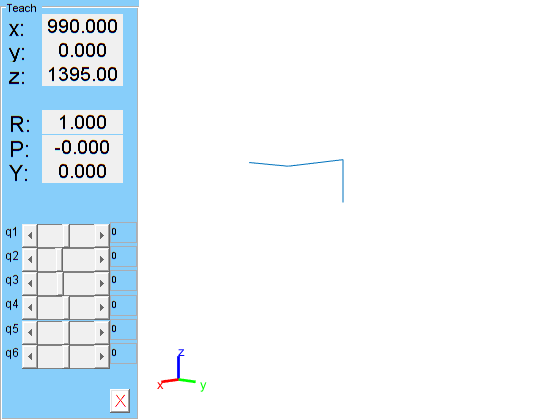

%Se muestra el robot
show(robot);
axis([-1000,1000,-1000,1000,-1000,1000])
axis off

### Modelo geométrico directo

- Modelo geometrico directo del robot asignado usando MTH.

clear
threshold = 1e-10;
%syms L1 L2 L3 L4 L5 L6;

% Primero se definen las longitudes de las articulaciones y el espacio de
% trabajo
L1=525;L2=150;L3=770;L4=100;L5=740;L6=100;
ws= [-1500 1500 -1500 1000 -50 2400];

%Se define cada una de las articulaciones con sus parametros y se grafica
%la tabla
plot_options = {'workspace',ws,'scale',.5,'view',[125 25], 'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset', 0, 'qlim', [0 2*pi], 'modified');
L(2) = Link('revolute','alpha',pi/2,'a',L2,'d',0,'offset', pi/2, 'qlim',  [-pi/2 8*pi/9], 'modified');
L(3) = Link('revolute','alpha',0,'a',L3,'d',0,'offset', 0, 'qlim', [-17*pi/18 29*pi/18], 'modified');
L(4) = Link('revolute','alpha',pi/2,'a',L4,'d',L5,'offset', 0, 'qlim', [-10*pi/9 10*pi/9], 'modified');
L(5) = Link('revolute','alpha',pi/2,'a',0,'d',0,'offset', pi, 'qlim', [-7*pi/4 7*pi/4], 'modified');
L(6) = Link('revolute','alpha',pi/2,'a',0,'d',L6,'offset', pi/2, 'qlim', [-5*pi/2 5*pi/2], 'modified');

Robot5 = SerialLink(L,'name','Fanuc M-161B','plotopt',plot_options)

 
Robot5 = 
 
Fanuc M-161B (6 axis, RRRRRR, modDH, fastRNE)                    
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        525|          0|          0|          0|
|  2|         q2|          0|        150|      1.571|      1.571|
|  3|         q3|          0|        770|          0|          0|
|  4|         q4|        740|        100|      1.571|          0|
|  5|         q5|          0|          0|      1.571|      3.142|
|  6|         q6|        100|          0|      1.571|      1.571|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0           

- MTH para cada eslabón.

%Se define y muestra la MTH para cada eje
syms gamma1 gamma2 gamma3 gamma4 gamma5 gamma6
MTH_01 = mapSymType(vpa(L(1).A(gamma1),2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x))

$$MTH\_01 = \left(\begin{array}{cccc} \cos\left(\gamma_{1}\right) & -1.0\,\sin\left(\gamma_{1}\right) & 0 & 0\\ \sin\left(\gamma_{1}\right) & \cos\left(\gamma_{1}\right) & 0 & 0\\ 0 & 0 & 1.0 & 525.0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

MTH_12 = mapSymType(vpa(L(2).A(gamma2),2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x))

$$MTH\_12 = \left(\begin{array}{cccc} \cos\left(\gamma_{2}+1.570796326734125614166259765625\right) & -1.0\,\sin\left(\gamma_{2}+1.570796326734125614166259765625\right) & 0 & 150.0\\ 0 & 0 & -1.0 & 0\\ \sin\left(\gamma_{2}+1.570796326734125614166259765625\right) & \cos\left(\gamma_{2}+1.570796326734125614166259765625\right) & 0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

MTH_23 = vpa(mapSymType(vpa(L(3).A(gamma3),2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x)),2)

$$MTH\_23 = \left(\begin{array}{cccc} \cos\left(\gamma_{3}\right) & -1.0\,\sin\left(\gamma_{3}\right) & 0 & 770.0\\ \sin\left(\gamma_{3}\right) & \cos\left(\gamma_{3}\right) & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

MTH_34 = vpa(mapSymType(vpa(L(4).A(gamma4),2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x)),2)

$$MTH\_34 = \left(\begin{array}{cccc} \cos\left(\gamma_{4}\right) & -1.0\,\sin\left(\gamma_{4}\right) & 0 & 100.0\\ 0 & 0 & -1.0 & -740.0\\ \sin\left(\gamma_{4}\right) & \cos\left(\gamma_{4}\right) & 0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

MTH_45 = mapSymType(vpa(L(5).A(gamma5),2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x))

$$MTH\_45 = \left(\begin{array}{cccc} -1.0\,\cos\left(\gamma_{5}\right) & \sin\left(\gamma_{5}\right) & 0 & 0\\ 0 & 0 & -1.0 & 0\\ -1.0\,\sin\left(\gamma_{5}\right) & -1.0\,\cos\left(\gamma_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

MTH_56 = mapSymType(vpa(L(6).A(gamma6),2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x))

$$MTH\_56 = \left(\begin{array}{cccc} \cos\left(\gamma_{6}+1.570796326734125614166259765625\right) & -1.0\,\sin\left(\gamma_{6}+1.570796326734125614166259765625\right) & 0 & 0\\ 0 & 0 & -1.0 & -100.0\\ \sin\left(\gamma_{6}+1.570796326734125614166259765625\right) & \cos\left(\gamma_{6}+1.570796326734125614166259765625\right) & 0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

-  Formulación del modelo geométrico directo (cinemática directa)

%Se establece la MTH para el efector del robot, se calcula y se muestra
MTH6T=[1 0 0 0;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
Robot5.tool = MTH6T;
H = vpa(mapSymType(vpa(MTH_01*MTH_12*MTH_23*MTH_34*MTH_45*MTH_56*MTH6T, 2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x)),2)

- Ubicación efector final

%Se obtienen los valores para los valores de articulacion

q=[0.5, 0.2, 0.4, 0.5, 0, 1.5];
%q=[-pi/2, 0.3, 0, pi/2, 0.4, 1.2];
%q=[0, 1, -0.5 2 1 0.5];
%q=[-1, -0.3, -pi/5, 0.4 0.2 1];
TCP = Robot5.fkine(q)

TCP = 	1.0e+03 *

   -0.0003    0.0006    0.0007    0.5562
   -0.0006   -0.0007    0.0004    0.3039
    0.0008   -0.0003    0.0006    1.8365
         0         0         0    0.0010


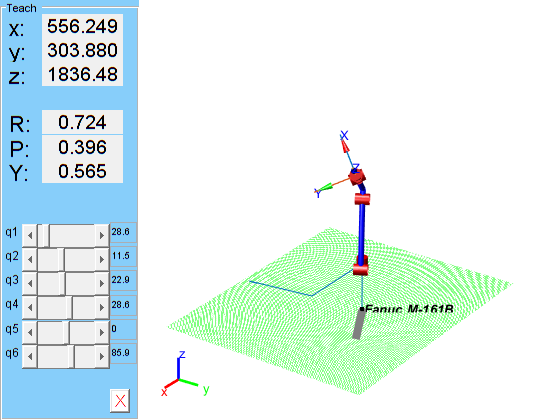

Robot5.teach(q); 

- Posición en coordenadas cartesianas y la orientación en ángulos fijos (Corke).

% Se hace la conversion a Coordenadas Cartesianas
    TCP_cart=transl(TCP)

TCP_cart = 	1.0e+03 *

    0.5562
    0.3039
    1.8365


% Se hace la conversion a Coordenadas Ángulos fijos
    TCP_rpy=tr2rpy(TCP)

TCP_rpy =    -0.6112    0.8100   -1.9435


**Posicion 1**

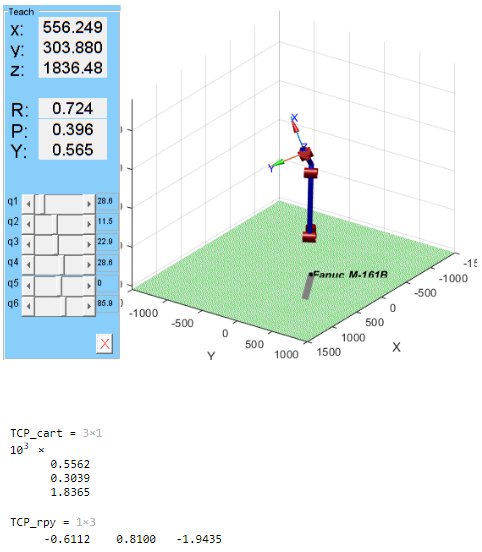

**Posicion 2**

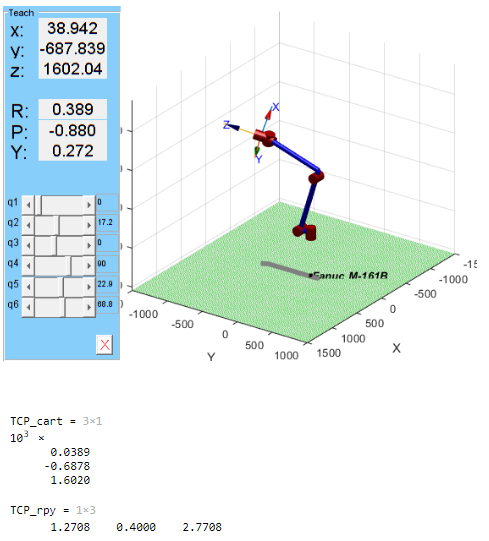

**Posicion 3**

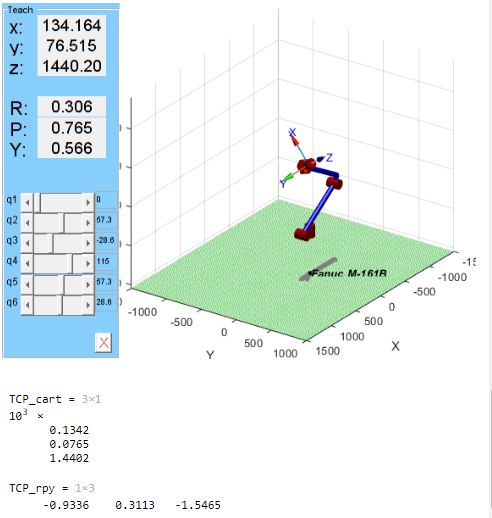

**Posicion 4**

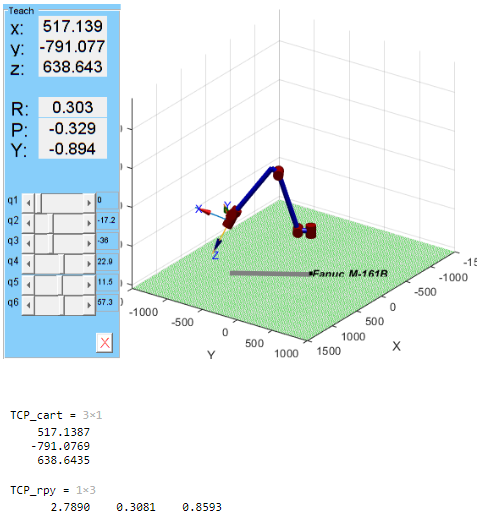

### Modelo geométrico inverso

- Haciendo uso del metodo geométrico visto en clase juntoo con el método algebráico encontramos los valores de los ángulos de las juntas en diferentes posiciones.

%Posicion 1    
x0=1000;y0=600;z0=1000;roll=0;pitch=90;yaw=180;

%Posicion 2    
%x0=67;y0=-911;z0=1895;roll=-26;pitch=-10;yaw=53;
%Posicion 3    
%x0=1306;y0=430;z0=1279;roll=-133;pitch=43;yaw=111;
%Posicion 4    
%x0=323;y0=107;z0=1988;roll=-22;pitch=42;yaw=-173;



ROT=rpy2r(roll,pitch,yaw,'deg');

p0=[x0;y0;z0];
pw=p0 -L6*ROT(:,3);
xw=pw(1);
yw=pw(2);
zw=pw(3);
r=sqrt(xw^2+yw^2);
Lxy=r-L2;
Lz=zw-L1;
Lp=sqrt(Lxy^2+Lz^2);

q1=atan2(yw,xw)

q1 = 0.5880


alpha=atan2(abs(Lz),abs(Lxy));
cosB=(L3^2+Lp^2-L5^2)/(2*L3*Lp);
senB=sqrt(1-cosB^2);
beta=atan2(abs(senB),abs(cosB));
q2=-((pi/2)-(alpha+beta))

q2 = -0.3140


cosY=(L3^2+L5^2-Lp^2)/(2*L3*L5);
senY=sqrt(1-cosY^2);
gama=atan2(senY,cosY);
phi=pi-gama;
q3=(pi/2)-phi

q3 = -0.0411


MTH03=L(1).A(q1)*L(2).A(q2)*L(3).A(q3)

MTH03 = 	1.0e+03 *

    0.0003   -0.0008    0.0006    0.3227
    0.0002   -0.0005   -0.0008    0.2151
    0.0009    0.0003    0.0000    1.2573
         0         0         0    0.0010


MTH36=MTH03^-1*TCP

MTH36 =     0.5131   -0.2684    0.8153  627.6860
    0.7748   -0.2640   -0.5745  -26.9327
    0.3694    0.9264    0.0725   55.7078
         0         0         0    1.0000


ang=tr2eul(MTH36,'deg') %Corresponden a los valores de q4 q5 y q6 

ang =   -35.1686   85.8402  111.7395


Realizamos el mismo procedimiento para las 4 posiciones de la máquina diferentes y completamos la tabla:

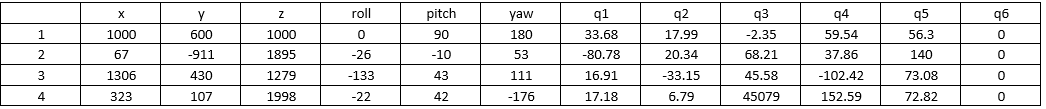

Vemos ahora la representación de cada una de las imágenes:

**Posición 1:**

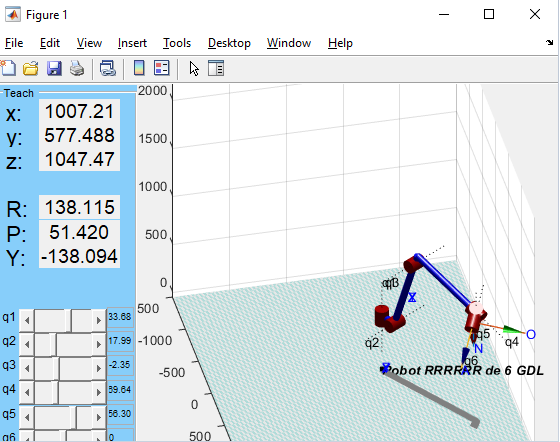

**Posición 2:**

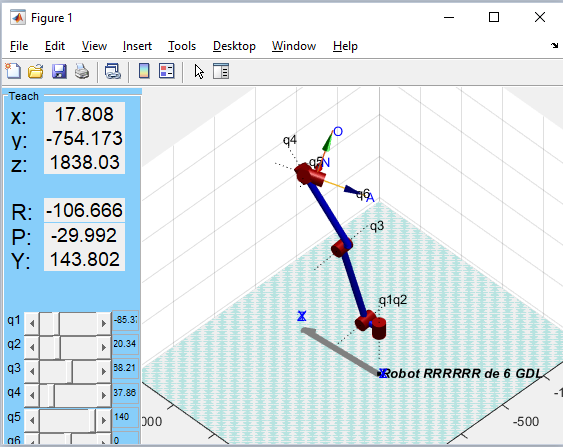

**Posición 3:**

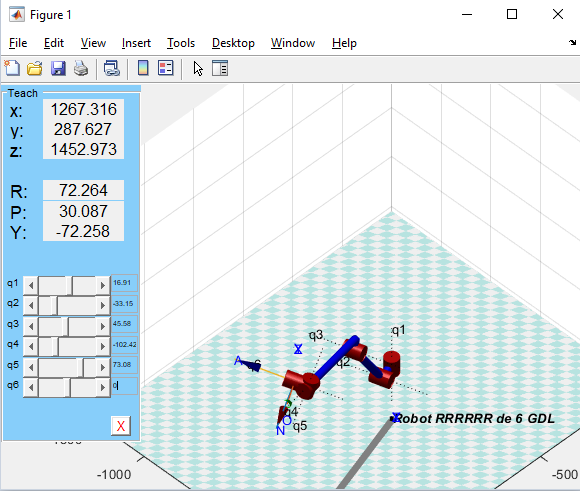

**Posición 4:**

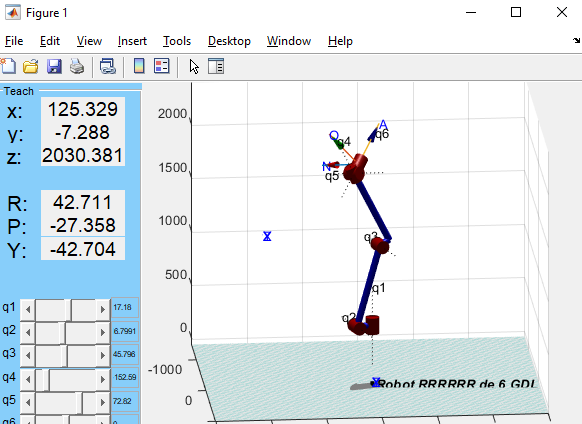

### Modelo diferencial de primer orden

Con los valores númericos de longitudes y desplazamientos de los eslabones del robot asignado se realiza la obtención del jacobiano en términos de los ángulos de articulación.

Se obtienen las matrices de transformación de cada uno de las tramas en la posición de Home

MTH_01 = L(1).A(0)

MTH_01 =      1     0     0     0
     0     1     0     0
     0     0     1   525
     0     0     0     1


MTH_12 = L(2).A(0)

MTH_12 =     0.0000   -1.0000         0  150.0000
    0.0000    0.0000   -1.0000         0
    1.0000    0.0000    0.0000         0
         0         0         0    1.0000


MTH_23 = L(3).A(0)

MTH_23 =      1     0     0   770
     0     1     0     0
     0     0     1     0
     0     0     0     1


MTH_34 = L(4).A(0)

MTH_34 =     1.0000         0         0  100.0000
         0    0.0000   -1.0000 -740.0000
         0    1.0000    0.0000    0.0000
         0         0         0    1.0000


MTH_45 = L(5).A(0)

MTH_45 =    -1.0000   -0.0000         0         0
    0.0000   -0.0000   -1.0000         0
    0.0000   -1.0000    0.0000         0
         0         0         0    1.0000


MTH_56 = L(6).A(0)

MTH_56 =     0.0000   -1.0000         0         0
    0.0000    0.0000   -1.0000 -100.0000
    1.0000    0.0000    0.0000    0.0000
         0         0         0    1.0000


Se obtienen las MTH con respecto a la base

MTH_02 = MTH_01*MTH_12

MTH_02 =     0.0000   -1.0000         0  150.0000
    0.0000    0.0000   -1.0000         0
    1.0000    0.0000    0.0000  525.0000
         0         0         0    1.0000


MTH_03 = MTH_02*MTH_23

MTH_03 = 	1.0e+03 *

    0.0000   -0.0010         0    0.1500
    0.0000    0.0000   -0.0010    0.0000
    0.0010    0.0000    0.0000    1.2950
         0         0         0    0.0010


MTH_04 = MTH_03*MTH_34

MTH_04 = 	1.0e+03 *

    0.0000   -0.0000    0.0010    0.8900
    0.0000   -0.0010   -0.0000    0.0000
    0.0010    0.0000   -0.0000    1.3950
         0         0         0    0.0010


MTH_05 = MTH_04*MTH_45

MTH_05 = 	1.0e+03 *

    0.0000   -0.0010    0.0000    0.8900
   -0.0000    0.0000    0.0010    0.0000
   -0.0010   -0.0000   -0.0000    1.3950
         0         0         0    0.0010


MTH_06 = MTH_05*MTH_56

MTH_06 = 	1.0e+03 *

    0.0000   -0.0000    0.0010    0.9900
    0.0010    0.0000   -0.0000    0.0000
   -0.0000    0.0010    0.0000    1.3950
         0         0         0    0.0010


Se obtienen los ejes de rotación instantaneos

Z_00 = MTH_01(1:3,3);
Z_01 = Z_00;
Z_02 = MTH_02(1:3,3);
Z_03 = MTH_03(1:3,3);
Z_04 = MTH_04(1:3,3);
Z_05 = MTH_05(1:3,3);
Z_06 = MTH_06(1:3,3);

Se obtienen los vectores de posición absoluta

P_01 = MTH_01(1:3,4);
P_02 = MTH_02(1:3,4);
P_03 = MTH_03(1:3,4);
P_04 = MTH_04(1:3,4);
P_05 = MTH_05(1:3,4);
P_06 = MTH_06(1:3,4);

Se obtiene los vectores de posción relativa

P_16 = P_06 - P_01;
P_26 = P_06 - P_02;
P_36 = P_06 - P_03;
P_46 = P_06 - P_04;
P_56 = P_06 - P_05;

Se obtiene el jacobiano por el método geométrico 

J_Fanuc_Geo = [cross(Z_01,P_16) cross(Z_02,P_26) cross(Z_03,P_36)... 
    cross(Z_04,P_46) cross(Z_05,P_56) cross(Z_06,P_56); Z_01 Z_02 Z_03...
    Z_04 Z_05 Z_06]

J_Fanuc_Geo =    -0.0000 -870.0000 -100.0000   -0.0000   -0.0000    0.0000
  990.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
         0  840.0000  840.0000    0.0000 -100.0000    0.0000
         0         0         0    1.0000    0.0000    1.0000
         0   -1.0000   -1.0000   -0.0000    1.0000   -0.0000
    1.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000


Se obtiene el jacobiano con ayuda del RVC a modo de comprobación

J_Fanuc = Robot5.jacob0(q)

J_Fanuc = 	1.0e+03 *

   -0.3039   -1.1509   -0.4887    0.0000    0.0205         0
    0.5562   -0.6288   -0.2670   -0.0000    0.0658         0
    0.0000    0.4838    0.6368   -0.0000   -0.0724         0
   -0.0000    0.0005    0.0005    0.0007   -0.0007    0.0007
    0.0000   -0.0009   -0.0009    0.0004    0.0006    0.0004
    0.0010         0         0    0.0006    0.0004    0.0006


Con el jacobiano obtenido, es posible conocer las velocidades de articulación a partir de un valor dado de velocidades lineales y angulares para el TCP.

Valores de las articulaciones ***q*** para la primera configuración obtenida por medio de la cinemática inversa

Q = zeros(6,1); 
q_deg = [66.57 13.82 -35.44 -68.37 23.42 0];
for i = 1:length(q_deg) 
    Q(i,1) = deg2rad(q_deg(i)); 
end

Se calcula el jacobiano para la configuración requerida

J_Fanuc_b = Robot5.jacob0(Q)

J_Fanuc_b =  -692.5170 -207.0021   90.3083  -18.8562   58.6187         0
  340.3777 -477.6672  208.3908   -6.6653  -79.2566         0
    0.0000  620.7604  804.6922  -34.3486  -16.8001         0
    0.0000    0.9175    0.9175    0.3697   -0.4744    0.6568
         0   -0.3976   -0.3976    0.8530   -0.1677    0.5863
    1.0000         0         0   -0.3684   -0.8642   -0.4743


V_H = [100; 200; 50]; ome_H = [5; 10; -5];
Vel = [V_H; ome_H]

Vel =    100
   200
    50
     5
    10
    -5


Se obtien el vector de velocidades de articulación para la configuración dada

Q_p = inv(J_Fanuc_b)*Vel 

Q_p =    -0.2058
   -0.3938
    0.8645
   11.5502
    0.2676
    0.6478
